% Auto-generated by cameraCalibrator app on 23-Sep-2022
%-------------------------------------------------------


% Define images to process
imageFileNames = {'/Users/rakhi/Desktop/10.jpeg',...
    '/Users/rakhi/Desktop/9.jpeg',...
    '/Users/rakhi/Desktop/8.jpeg',...
    '/Users/rakhi/Desktop/7.jpeg',...
    '/Users/rakhi/Desktop/6.jpeg',...
    '/Users/rakhi/Desktop/5.jpeg',...
    '/Users/rakhi/Desktop/4.jpeg',...
    '/Users/rakhi/Desktop/3.jpeg',...
    '/Users/rakhi/Desktop/2.jpeg',...
    '/Users/rakhi/Desktop/1.jpeg',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);

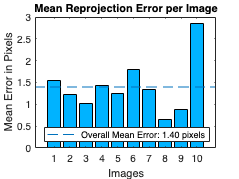

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 21;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

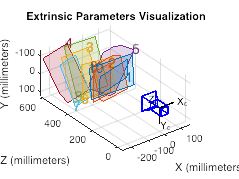


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1160.0469 +/- 11.1237    1158.5178 +/- 10.9550 ]
Principal point (pixels):[  547.6532 +/- 2.6145      358.7546 +/- 3.3394  ]
Radial distortion:       [    0.1792 +/- 0.0126       -0.3098 +/- 0.0468  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.3525 +/- 0.0060       -0.1008 +/- 0.0084        3.0983 +/- 0.0010  ]
                         [   -0.1623 +/- 0.0070       -0.1534 +/- 0.0072        1.5691 +/- 0.0011  ]
                         [   -0.3932 +/- 0.0037        0.3318 +/- 0.0043        1.5475 +/- 0.0010  ]
                         [   -0.4915 +/- 0.0036        0.3237 +/- 0.0043        1.3969 +/- 0.0011  ]
                         [    0.0316 +/- 0.0037        0.1662 +/- 0.0049        2.1358 +/- 0.0006  ]
                         [   -0.2403 +/- 0.0035        0.1591 +/- 0.0029       -1.5996 +/- 0.0007  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')